

% Reliability of information in a structure between two sessions

clear all
cd /media/DataMOBsRAIDN/PFC_InteroceptiveTuning/DecodingAnalysis
load('DataDecoding_PFC_BR.mat')
Var = 'BR'

Var = 'BR'

Sess1 = 'Wake_Home';
Sess2 = 'Sleep';
disp('ok')

ok



Opts.ParamBinLims = [1.5:1:12]%1.5 for sleep

Opts = struct with fields:
     TempBinsize: 1
       BinNumber: 5
    ParamBinLims: [1.5000 2.5000 3.5000 4.5000 5.5000 6.5000 7.5000 8.5000 9.5000 10.5000 11.5000]


MinSamples = 10;

% zscore
for mm = 1:length(spike_dat.(Sess1))
%     Std_neur = std(spike_dat.(Sess1){mm}')';
%     Std_neur1 = repmat(Std_neur,1,size(spike_dat.(Sess1){mm},2));
%     Mean_neur = mean(spike_dat.(Sess1){mm}')';
%     Mean_neur1 = repmat(Mean_neur,1,size(spike_dat.(Sess1){mm},2));
%     spike_dat.(Sess1){mm} = (spike_dat.(Sess1){mm}-Mean_neur1)./Std_neur1;
%     Std_neur2 = repmat(Std_neur,1,size(spike_dat.(Sess2){mm},2));
%     Mean_neur2 = repmat(Mean_neur,1,size(spike_dat.(Sess2){mm},2));
%     spike_dat.(Sess2){mm} = (spike_dat.(Sess2){mm}-Mean_neur2)./Std_neur2;
    
    spike_dat.(Sess1){mm} = zscore(spike_dat.(Sess1){mm}')';
    spike_dat.(Sess2){mm} = zscore(spike_dat.(Sess2){mm}')';
end

cd /media/DataMOBsRAIDN/PFC_InteroceptiveTuning/PFCTuningByVarAndPeriod
T_Sess1 = load('BRTuning_Wake_Explo_PFC_0.2s_6ParamBinNumber.mat','TuningCurves');
T_Sess2 = load('BRTuning_Sleep_PFC_0.2s_6ParamBinNumber.mat','TuningCurves');

for mm = 1:length(spike_dat.(Sess1))
    P1 = cellfun(@(x) x.AnovaInfo,T_Sess1.TuningCurves{mm});
    P2 = cellfun(@(x) x.AnovaInfo,T_Sess2.TuningCurves{mm});
    Good = find(P1<0.01 & P2<0.01);
    spike_dat.(Sess1){mm} = spike_dat.(Sess1){mm}(Good,:);
    spike_dat.(Sess2){mm} = spike_dat.(Sess2){mm}(Good,:);
end

## Recalculate the tuning curves and see if they're the same in both sessions

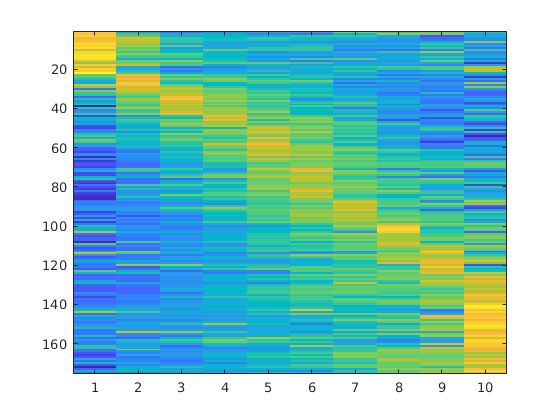

TuningAll_1 = [];
for mm = 1:length(spike_dat.(Sess1))
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.(Sess1){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess1){mm}<Opts.ParamBinLims(ii+1));
        Tuning_temp(:,ii) = nanmean(spike_dat.(Sess1){mm}(:,BinsOI),2);
    end
    TuningAll_1 = [TuningAll_1;Tuning_temp];
end
[~,ind]=max(zscore(TuningAll_1'));
[~,ind]=sort(ind);
figure
imagesc(nanzscore(TuningAll_1(ind,:)')')

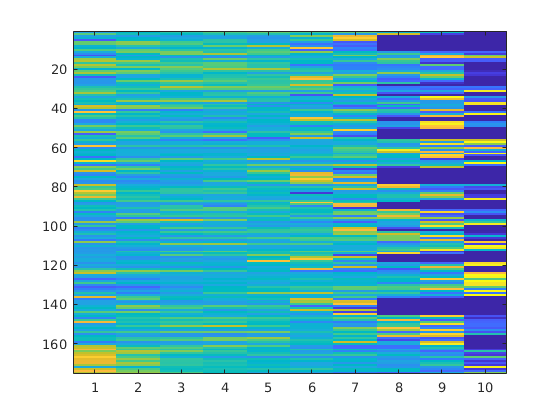


TuningAll_2 = [];
for mm = 1:length(spike_dat.(Sess2))
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.(Sess2){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess2) ...
            {mm}<Opts.ParamBinLims(ii+1));
        Tuning_temp(:,ii) = nanmean(spike_dat.(Sess2){mm}(:,BinsOI),2);
    end
    TuningAll_2 = [TuningAll_2;Tuning_temp];
end
figure
imagesc(nanzscore(TuningAll_2(ind,:)')')

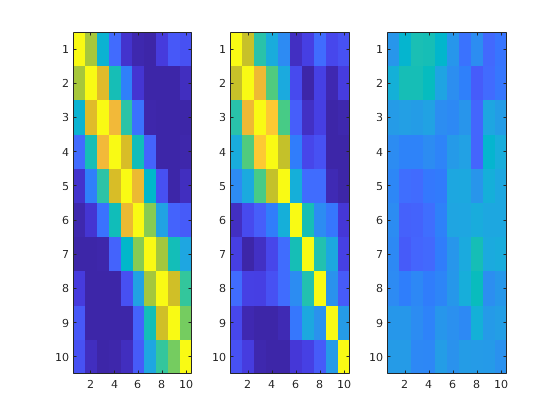


figure
subplot(131)
imagesc(corr(nanzscore(TuningAll_1')','rows','pairwise'))
caxis([-0.5 1])
subplot(132)
imagesc(corr(nanzscore(TuningAll_2')','rows','pairwise'))
caxis([-0.5 1])
subplot(133)
imagesc(corr(nanzscore(TuningAll_1')',nanzscore(TuningAll_2')','rows','pairwise'))
caxis([-0.5 1])

clear Data_todecode TrNumPerMouse

TuningAll_1 = [];
for mm = 1:length(spike_dat.(Sess1))
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.(Sess1){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess1){mm}<Opts.ParamBinLims(ii+1));
        Tuning_temp(:,ii) = nanmean(spike_dat.(Sess1){mm}(:,BinsOI(1:2:end)),2);
        Data_todecode{mm}{ii} = spike_dat.(Sess1){mm}(:,BinsOI(2:2:end));
    end
    TuningAll_1 = [TuningAll_1;Tuning_temp];
end

for mm = 1:length(spike_dat.(Sess2))
    TrNumPerMouse(mm,:) = cellfun(@(x) size(x,2),Data_todecode{mm});
end

TrNumToUse = max([20,min(TrNumPerMouse(:))]);

X_Train = [];
X_Test = [];

for mm = 1:length(spike_dat.(Sess1))
    Tuning_temp = [];
    Tuning_temp2 = [];
    Y_Train = [];
    Y_Test = [];
    for ii = 1:length(Opts.ParamBinLims)-1
        % Training
        BinsOI = find(VarOfInterest.(Sess1){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess1){mm}<Opts.ParamBinLims(ii+1));
        BinsOI = BinsOI(1:2:end);
        if length(BinsOI)<20
            BinsOI = BinsOI(randi(length(BinsOI),[1,TrNumToUse]));
        else
            BinsOI = BinsOI(randperm(length(BinsOI),TrNumToUse));
        end

        Tuning_temp = [Tuning_temp,spike_dat.(Sess1){mm}(:,BinsOI)];
        Y_Train = [Y_Train,zeros(1,length(BinsOI))+ii];

        % Testing
        BinsOI = find(VarOfInterest.(Sess1){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess1){mm}<Opts.ParamBinLims(ii+1));
        BinsOI = BinsOI(2:2:end);
        if length(BinsOI)<20
            BinsOI = BinsOI(randi(length(BinsOI),[1,TrNumToUse]));
        else
            BinsOI = BinsOI(randperm(length(BinsOI),TrNumToUse));
        end

        Tuning_temp2 = [Tuning_temp2,spike_dat.(Sess1){mm}(:,BinsOI)];
        Y_Test = [Y_Test,zeros(1,length(BinsOI))+ii];


    end
    X_Test = [X_Test;Tuning_temp2];
    X_Train = [X_Train;Tuning_temp];

end

[Mdl,Fit] = lasso(X_Train',Y_Train);

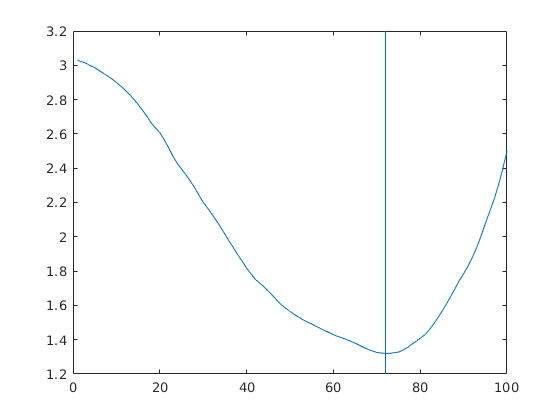

for l = 1:size(Mdl,2)
    Err(l) = nanmean(sqrt((X_Test'*Mdl(:,l)+Fit.Intercept(l) - Y_Test').^2))    ;

end
figure
plot(Err)
[~,ind] = min(Err);
LambdaToUse = Fit.Lambda(ind);
line([ind ind],ylim)

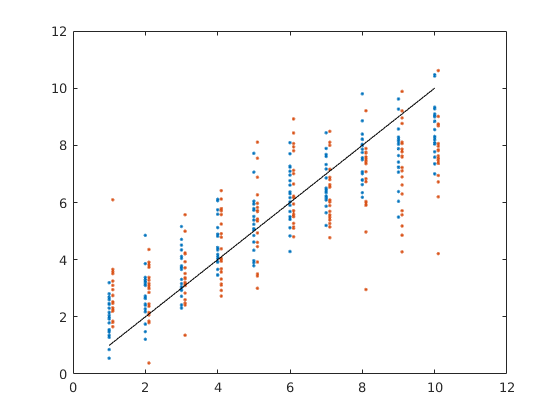


figure
plot(Y_Test,X_Train'*Mdl(:,ind)+Fit.Intercept(ind),'.')
hold on
plot(Y_Test+0.1,X_Test'*Mdl(:,ind)+Fit.Intercept(ind),'.')
plot(Y_Test,Y_Test,'k')

% Decoding between sessions
clear Data_todecode TrNumPerMouse
clear Y_Train Y_Test X_Test X_Train
TuningAll_1 = [];
for mm = 1:length(spike_dat.(Sess1))
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.(Sess1){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess1){mm}<Opts.ParamBinLims(ii+1));
        Tuning_temp(:,ii) = nanmean(spike_dat.(Sess1){mm}(:,BinsOI(1:2:end)),2);
        Data_todecode{mm}{ii} = spike_dat.(Sess1){mm}(:,BinsOI(2:2:end));
    end
    TuningAll_1 = [TuningAll_1;Tuning_temp];
end

for mm = 1:length(spike_dat.(Sess1))
    TrNumPerMouse(mm,:) = cellfun(@(x) size(x,2),Data_todecode{mm});
end

TrNumToUse = max([20,min(TrNumPerMouse(:))]);

X_Train = [];
X_Test = [];

for mm = 1:length(spike_dat.(Sess1))
    Tuning_temp = [];
    Tuning_temp2 = [];
    Y_Train = [];
    Y_Test = [];
    for ii = 1:length(Opts.ParamBinLims)-1
        % Training
        BinsOI = find(VarOfInterest.(Sess1){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess1){mm}<Opts.ParamBinLims(ii+1));
        BinsOI = BinsOI(1:2:end);
        if length(BinsOI)<20
            BinsOI = BinsOI(randi(length(BinsOI),[1,TrNumToUse]));
        else
            BinsOI = BinsOI(randperm(length(BinsOI),TrNumToUse));
        end

        Tuning_temp = [Tuning_temp,spike_dat.(Sess1){mm}(:,BinsOI)];
        Y_Train = [Y_Train,zeros(1,length(BinsOI))+ii];

        % Testing
        BinsOI = find(VarOfInterest.(Sess2){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess2){mm}<Opts.ParamBinLims(ii+1));
        if length(BinsOI)>0
            if length(BinsOI)<20

                BinsOI = BinsOI(randi(length(BinsOI),[1,TrNumToUse]));
            else
                BinsOI = BinsOI(randperm(length(BinsOI),TrNumToUse));
            end

            Tuning_temp2 = [Tuning_temp2,spike_dat.(Sess2){mm}(:,BinsOI)];
            Y_Test = [Y_Test,zeros(1,length(BinsOI))+ii];
        else
            Tuning_temp2 = [Tuning_temp2,nan(size(spike_dat.(Sess2){mm},1),TrNumToUse)];
            Y_Test = [Y_Test,zeros(1,TrNumToUse)*NaN];

        end

    end
    X_Test = [X_Test;Tuning_temp2];
    X_Train = [X_Train;Tuning_temp];

end

[Mdl,Fit] = lasso(X_Train',Y_Train);

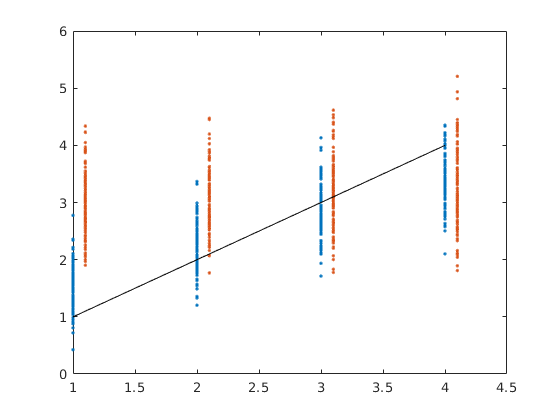

figure
plot(Y_Train,X_Train'*Mdl(:,ind)+Fit.Intercept(ind),'.')
hold on
plot(Y_Test+0.1,X_Test'*Mdl(:,ind)+Fit.Intercept(ind),'.')
plot(Y_Test,Y_Test,'k')

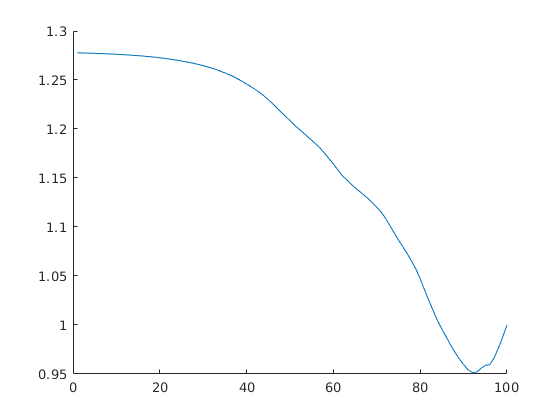


for l = 1:size(Mdl,2)
    Err_Tr(l) = nanmean(sqrt((X_Test'*Mdl(:,l)+Fit.Intercept(l) - Y_Test').^2))    ;

end

figure
hold on
plot(Err_Tr)

% Decoding between sessions - random
clear Data_todecode TrNumPerMouse
clear Y_Train Y_Test X_Test X_Train
TuningAll_1 = [];
for mm = 1:length(spike_dat.(Sess1))
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.(Sess1){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess1){mm}<Opts.ParamBinLims(ii+1));
        Tuning_temp(:,ii) = nanmean(spike_dat.(Sess1){mm}(:,BinsOI(1:2:end)),2);
        Data_todecode{mm}{ii} = spike_dat.(Sess1){mm}(:,BinsOI(2:2:end));
    end
    TuningAll_1 = [TuningAll_1;Tuning_temp];
end

for mm = 1:length(spike_dat.(Sess1))
    TrNumPerMouse(mm,:) = cellfun(@(x) size(x,2),Data_todecode{mm});
end

TrNumToUse = max([20,min(TrNumPerMouse(:))]);

X_Train = [];
X_Test = [];

for mm = 1:length(spike_dat.(Sess1))
    Tuning_temp = [];
    Tuning_temp2 = [];
    Y_Train = [];
    Y_Test = [];
            varoi_rand = VarOfInterest.(Sess1){mm}(randperm(length(VarOfInterest.(Sess1){mm}),length(VarOfInterest.(Sess1){mm})));
            varoi_rand_2 = VarOfInterest.(Sess2){mm}(randperm(length(VarOfInterest.(Sess2){mm}),length(VarOfInterest.(Sess2){mm})));

    for ii = 1:length(Opts.ParamBinLims)-1
        % Training
        BinsOI = find(varoi_rand>Opts.ParamBinLims(ii) & varoi_rand<Opts.ParamBinLims(ii+1));
                BinsOI = BinsOI(1:2:end);
if length(BinsOI)<20
            BinsOI = BinsOI(randi(length(BinsOI),[1,TrNumToUse]));
        else
            BinsOI = BinsOI(randperm(length(BinsOI),TrNumToUse));
        end

        Tuning_temp = [Tuning_temp,spike_dat.(Sess1){mm}(:,BinsOI)];
        Y_Train = [Y_Train,zeros(1,length(BinsOI))+ii];

        % Testing
        BinsOI = find(varoi_rand_2>Opts.ParamBinLims(ii) & varoi_rand_2<Opts.ParamBinLims(ii+1));
        if length(BinsOI)>0
            if length(BinsOI)<20

                BinsOI = BinsOI(randi(length(BinsOI),[1,TrNumToUse]));
            else
                BinsOI = BinsOI(randperm(length(BinsOI),TrNumToUse));
            end

            Tuning_temp2 = [Tuning_temp2,spike_dat.(Sess2){mm}(:,BinsOI)];
            Y_Test = [Y_Test,zeros(1,length(BinsOI))+ii];
        else
            Tuning_temp2 = [Tuning_temp2,nan(size(spike_dat.(Sess2){mm},1),TrNumToUse)];
            Y_Test = [Y_Test,zeros(1,TrNumToUse)*NaN];

        end

    end
    X_Test = [X_Test;Tuning_temp2];
    X_Train = [X_Train;Tuning_temp];

end

Mdl = lasso(X_Train',Y_Train);

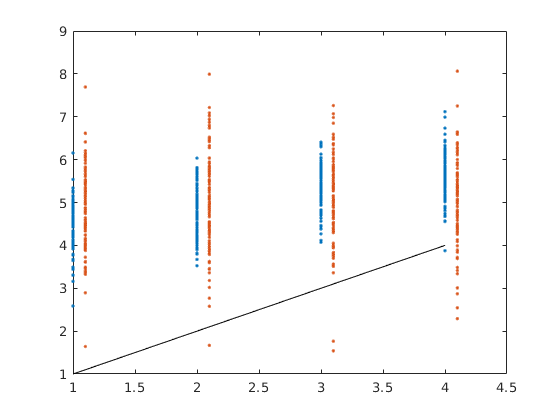

figure
plot(Y_Test,X_Train'*Mdl(:,40)+5,'.')
hold on
plot(Y_Test+0.1,X_Test'*Mdl(:,40)+5,'.')
plot(Y_Test,Y_Test,'k')

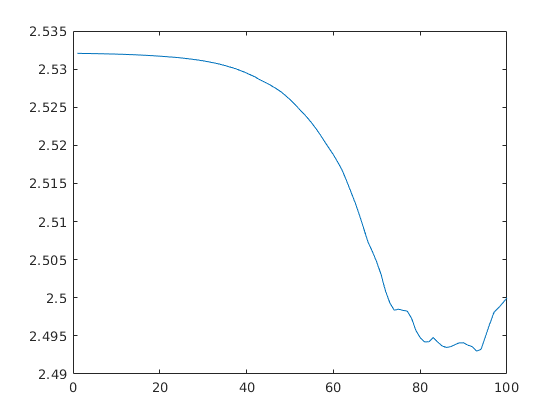


for l = 1:size(Mdl,2)
    Err(l) = nanmean(sqrt((X_Test'*Mdl(:,l)+5 - Y_Test').^2))    ;

end
figure
plot(Err)

%%%%%%%%%%%

% Do the stats - actual decoding

for perm = 1 : 100
    X_Train = [];
    X_Test = [];
    for mm = 1:length(spike_dat.(Sess1))
        Tuning_temp = [];
        Tuning_temp2 = [];
        Y_Train = [];
        Y_Test = [];
        for ii = 1:length(Opts.ParamBinLims)-1
            % Training
            BinsOI = find(VarOfInterest.(Sess1){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess1){mm}<Opts.ParamBinLims(ii+1));
%             BinsOI = BinsOI(1:2:end);
            order = randperm(length(BinsOI),length(BinsOI));
            BinsOI = BinsOI(order);
            if length(BinsOI)<20
                BinsOI = BinsOI(randi(length(BinsOI),[1,TrNumToUse]));
            else
                BinsOI = BinsOI(randperm(length(BinsOI),TrNumToUse));
            end

            Tuning_temp = [Tuning_temp,spike_dat.(Sess1){mm}(:,BinsOI)];
            Y_Train = [Y_Train,zeros(1,length(BinsOI))+ii];

            % Testing
            BinsOI = find(VarOfInterest.(Sess2){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess2){mm}<Opts.ParamBinLims(ii+1));
            order = randperm(length(BinsOI),length(BinsOI));
            BinsOI = BinsOI(order);
            if length(BinsOI)>0
                if length(BinsOI)<20

                    BinsOI = BinsOI(randi(length(BinsOI),[1,TrNumToUse]));
                else
                    BinsOI = BinsOI(randperm(length(BinsOI),TrNumToUse));
                end

                Tuning_temp2 = [Tuning_temp2,spike_dat.(Sess2){mm}(:,BinsOI)];
                Y_Test = [Y_Test,zeros(1,length(BinsOI))+ii];
            else
                Tuning_temp2 = [Tuning_temp2,nan(size(spike_dat.(Sess2){mm},1),TrNumToUse)];
                Y_Test = [Y_Test,zeros(1,TrNumToUse)*NaN];

            end

        end
        X_Test = [X_Test;Tuning_temp2];
        X_Train = [X_Train;Tuning_temp];

    end

[Mdl,Fit] = lasso(X_Train',Y_Train,'Lambda',LambdaToUse);
    Err_real(perm) = corr(X_Test'*Mdl+Fit.Intercept,Y_Test','rows','complete');;%nanmean(sqrt((X_Test'*Mdl+Fit.Intercept - Y_Test').^2))    ;
    Reconstructed_real(perm,:) = X_Test'*Mdl+Fit.Intercept;
end

% Do the stats - random decoding

for perm = 1 : 100
X_Train = [];
X_Test = [];
for mm = 1:length(spike_dat.(Sess1))
    Tuning_temp = [];
    Tuning_temp2 = [];
    Y_Train = [];
    Y_Test = [];
                varoi_rand = VarOfInterest.(Sess1){mm}(randperm(length(VarOfInterest.(Sess1){mm}),length(VarOfInterest.(Sess1){mm})));
            varoi_rand_2 = VarOfInterest.(Sess2){mm}(randperm(length(VarOfInterest.(Sess2){mm}),length(VarOfInterest.(Sess2){mm})));

    for ii = 1:length(Opts.ParamBinLims)-1
        % Training
        BinsOI = find(varoi_rand>Opts.ParamBinLims(ii) & varoi_rand<Opts.ParamBinLims(ii+1));
%                 BinsOI = BinsOI(1:2:end);
                            order = randperm(length(BinsOI),length(BinsOI));
            BinsOI = BinsOI(order);
if length(BinsOI)<20
            BinsOI = BinsOI(randi(length(BinsOI),[1,TrNumToUse]));
        else
            BinsOI = BinsOI(randperm(length(BinsOI),TrNumToUse));
        end

        Tuning_temp = [Tuning_temp,spike_dat.(Sess1){mm}(:,BinsOI)];
        Y_Train = [Y_Train,zeros(1,length(BinsOI))+ii];

        % Testing
        BinsOI = find(varoi_rand_2>Opts.ParamBinLims(ii) & varoi_rand_2<Opts.ParamBinLims(ii+1));
                    order = randperm(length(BinsOI),length(BinsOI));
            BinsOI = BinsOI(order);
        if length(BinsOI)>0
            if length(BinsOI)<20

                BinsOI = BinsOI(randi(length(BinsOI),[1,TrNumToUse]));
            else
                BinsOI = BinsOI(randperm(length(BinsOI),TrNumToUse));
            end

            Tuning_temp2 = [Tuning_temp2,spike_dat.(Sess2){mm}(:,BinsOI)];
            Y_Test = [Y_Test,zeros(1,length(BinsOI))+ii];
        else
            Tuning_temp2 = [Tuning_temp2,nan(size(spike_dat.(Sess2){mm},1),TrNumToUse)];
            Y_Test = [Y_Test,zeros(1,TrNumToUse)*NaN];

        end

    end
    X_Test = [X_Test;Tuning_temp2];
    X_Train = [X_Train;Tuning_temp];

end
    % randomize neurons
    X_Train = X_Train(randperm(size(X_Train,1),size(X_Train,1)),:);

[Mdl,Fit] = lasso(X_Train',Y_Train,'Lambda',LambdaToUse);
    Err_rand(perm) = corr(X_Test'*Mdl+Fit.Intercept,Y_Test','rows','complete');
        Reconstructed_rand(perm,:) = X_Test'*Mdl+Fit.Intercept;

    %Err_rand(perm) = nanmean(sqrt((X_Test'*Mdl+Fit.Intercept - Y_Test').^2));
end

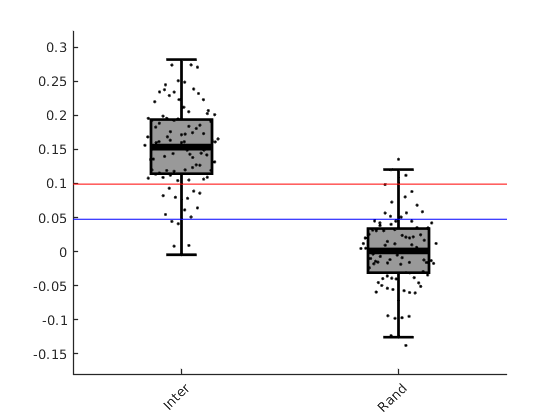

figure
A{1} = Err_real;
A{2} = Err_rand;
MakeSpreadAndBoxPlot_BM(A,[],[],{'Inter','Rand'},1,0)
line(xlim,[1 1]*prctile(A{1},5),'color','b')
line(xlim,[1 1]*prctile(A{2},95),'color','r')

    clear Reconstruct_av Reconstruct_av_rand
    for ii = 1:length(Opts.ParamBinLims)-1
Reconstruct_av(ii,:) = nanmean(Reconstructed_real(:,Y_Test==ii)');
Reconstruct_av_rand(ii,:) = nanmean(Reconstructed_rand(:,Y_Test==ii)');
    end

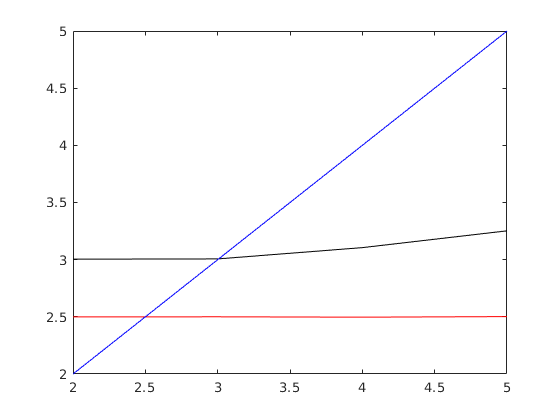

    figure
    plot(Opts.ParamBinLims(1:end-1), nanmean(Reconstruct_av'),'k')
    hold on
        plot(Opts.ParamBinLims(1:end-1),nanmean(Reconstruct_av_rand'),'r')
        plot(Opts.ParamBinLims(1:end-1),Opts.ParamBinLims(1:end-1),'b')

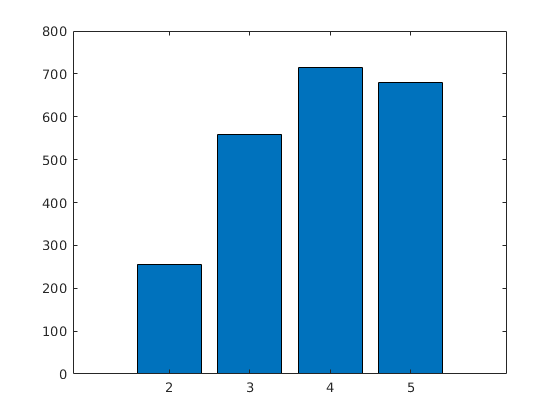

% Decoding between sessions - random
clear Data_todecode TrNumPerMouse
clear Y_Train Y_Test X_Test X_Train
TuningAll_1 = [];
for mm = 1:length(spike_dat.(Sess1))
    clear Tuning_temp
    for ii = 1:length(Opts.ParamBinLims)-1
        BinsOI = find(VarOfInterest.(Sess1){mm}>Opts.ParamBinLims(ii) & VarOfInterest.(Sess1){mm}<Opts.ParamBinLims(ii+1));
        Tuning_temp(:,ii) = nanmean(spike_dat.(Sess1){mm}(:,BinsOI(1:2:end)),2);
        Data_todecode{mm}{ii} = spike_dat.(Sess1){mm}(:,BinsOI(2:2:end));
    end
    TuningAll_1 = [TuningAll_1;Tuning_temp];
end

for mm = 1:length(spike_dat.(Sess1))
    TrNumPerMouse(mm,:) = cellfun(@(x) size(x,2),Data_todecode{mm});
end

TrNumToUse = max([20,min(TrNumPerMouse(:))]);
figure
bar(Opts.ParamBinLims(1:end-1),nanmean(TrNumPerMouse))